clear all
clc
close all

% Sim vars
SIMTIME = 3600;
SIMSTEP = 0.1;
simsize = SIMTIME/SIMSTEP;
n_contr = 9;
n_obsv = 6;
time = 0:SIMSTEP:SIMTIME;


z33 = zeros(3,3);
% x = [Np, Ep, psip, u, v, r, tauN, tauE, tauPSI]
% Ship characteristics
[M, D, Athr] = loadvars();
A = [z33,    eye(3),    z33;
     z33, -inv(M)*D, inv(M);
     z33,       z33,   Athr];
B = [z33, z33, -Athr]';
Bv = [z33, inv(M), z33]';
C = [eye(3,9)];
D = 0;
eig(A)

ans =          0
         0
    0.0011
    0.0035
         0
   -0.0069
   -0.0067
   -0.0050
   -0.0056


rank(ctrb(A, B))

ans = 9



%Ai = [zeros(3,3) C;
%      zeros(9,3) A];
%Bi = [zeros(3, 3); B];
%rank(ctrb(Ai, Bi))

n_augm = 3;
Ai = [A zeros(9,3);
      -C zeros(3,3)];
Bi = [B; zeros(3,3)];
N = [zeros(9,3); eye(3)];
Bvi = [Bv; zeros(3, 3)];
Ci = [C zeros(3,3)];
rank(ctrb(Ai, Bi))

ans = 12

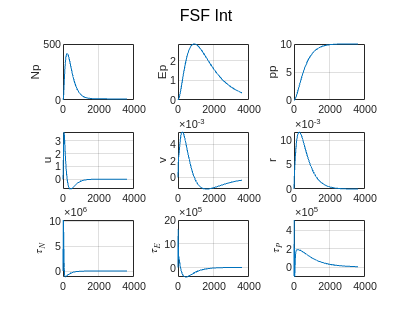

ref = [10;0;10];

des_lambda = [-0.001, -0.002, -0.003, -0.0050, -0.0051, -0.0052, -0.4, -0.5, -0.6, -0.07, -0.08, -0.09];
K = place(Ai, Bi, des_lambda);
Kfs = K(:,1:9);
Ki = -K(:,10:end);
xa_fsf = zeros(n_contr+n_augm, simsize+1);
sigmav1 = [10, 10, 10]';
for i = 1:simsize
    v = normrnd(0, sigmav1);
    u = -Kfs*xa_fsf(1:9,i) + Ki * xa_fsf(10:end, i);
    xadot = Ai * xa_fsf(:,i) + Bi * u + N*ref + Bvi * v;
    xa_fsf(:,i+1) = xa_fsf(:,i) + SIMSTEP * xadot;
end

Q = diag([1e5, 1e5, 1e5, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 10, 10, 10]);
R = diag([0.01, 0.01, 0.01]);
K = lqr(Ai, Bi, Q, R);
Kfs = K(:,1:9);
Ki = -K(:,10:end);
xa_lqr = zeros(n_contr+n_augm, simsize+1);
sigmav1 = [1e2, 1e2, 1e2]';
for i = 1:simsize
    v = normrnd(0, sigmav1);
    u = -Kfs*xa_lqr(1:9,i) + Ki * xa_lqr(10:end, i);
    xadot = Ai * xa_lqr(:,i) + Bi * u + N*ref + Bvi * v;
    xa_lqr(:,i+1) = xa_lqr(:,i) + SIMSTEP * xadot;
end

figure
sgtitle("FSF Int")
subplot(331), plot(time, xa_fsf(1, :)), grid, ylabel("Np")
subplot(332), plot(time, xa_fsf(2, :)), grid, ylabel("Ep")
subplot(333), plot(time, xa_fsf(3, :)), grid, ylabel("pp")

subplot(334), plot(time, xa_fsf(4, :)), grid, ylabel("u")
subplot(335), plot(time, xa_fsf(5, :)), grid, ylabel("v")
subplot(336), plot(time, xa_fsf(6, :)), grid, ylabel("r")

subplot(337), plot(time, xa_fsf(7, :)), grid, ylabel("$\tau_N$","Interpreter","latex")
subplot(338), plot(time, xa_fsf(8, :)), grid, ylabel("$\tau_E$","Interpreter","latex")
subplot(339), plot(time, xa_fsf(9, :)), grid, ylabel("$\tau_P$","Interpreter","latex")

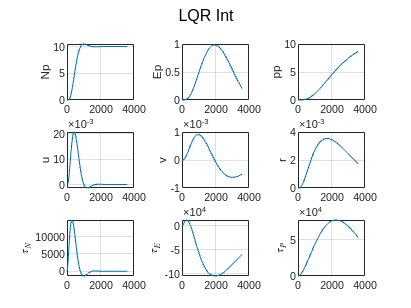


figure
sgtitle("LQR Int")
subplot(331), plot(time, xa_lqr(1, :)), grid, ylabel("Np")
subplot(332), plot(time, xa_lqr(2, :)), grid, ylabel("Ep")
subplot(333), plot(time, xa_lqr(3, :)), grid, ylabel("pp")

subplot(334), plot(time, xa_lqr(4, :)), grid, ylabel("u")
subplot(335), plot(time, xa_lqr(5, :)), grid, ylabel("v")
subplot(336), plot(time, xa_lqr(6, :)), grid, ylabel("r")

subplot(337), plot(time, xa_lqr(7, :)), grid, ylabel("$\tau_N$","Interpreter","latex")
subplot(338), plot(time, xa_lqr(8, :)), grid, ylabel("$\tau_E$","Interpreter","latex")
subplot(339), plot(time, xa_lqr(9, :)), grid, ylabel("$\tau_P$","Interpreter","latex")